clc
clear
close all

mass_payload = 20;
density = 1.225;
vehicle_position = [0; 0; 0];
vehicle_velocity = [50; 0; -20];
vehicle_orientation = [0; 0; 0];

Nb = 4;
Span = 1;
RootBladeDistance = 0.05;
root_theta = 10;
twist_rate = 0;
root_chord = 0.17;
lambda_chord = 1;
disk_area = pi * (Span - RootBladeDistance)^2;
induced_velocity = -1.5;

RPM = 500;

blade_integrator = 'Trapezoidal'; 

values = floor(logspace(0, 2, 50));
values = unique(values);
values(1)=[]

values =      2     3     4     5     6     7     8     9    10    11    12    13    15    16    18    20    22    24    26    29    32    35    39    42    47    51    56    62    68    75    82    91   100



azimutal_points_vec = 200;
No_elements_vec = values;

f_vec_x = zeros(length(azimutal_points_vec), length(No_elements_vec));
e_vec_x = zeros(length(azimutal_points_vec), length(No_elements_vec));

f_vec_y = zeros(length(azimutal_points_vec), length(No_elements_vec));
e_vec_y = zeros(length(azimutal_points_vec), length(No_elements_vec));

f_vec_z = zeros(length(azimutal_points_vec), length(No_elements_vec));
e_vec_z = zeros(length(azimutal_points_vec), length(No_elements_vec));

counter = 0;

for c = 1:length(azimutal_points_vec)
    for b = 1:length(No_elements_vec)

        azimutal_points = azimutal_points_vec(c);
        No_elements = No_elements_vec(b);

        counter = counter + 1;

        fprintf (">> [%d] E = %d | A = %d\n", counter, No_elements, azimutal_points)
        sim_init_rotor_simulation
        [F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
        f_vec_x(c, b) = F_rotor(1);
        f_vec_y(c, b) = F_rotor(2);
        f_vec_z(c, b) = F_rotor(3);

        clear SIM VEHICLE ROTOR BLADE ATMOSPHERE

    end
end

>> [1] E = 2 | A = 200
>> [2] E = 3 | A = 200
>> [3] E = 4 | A = 200
>> [4] E = 5 | A = 200
>> [5] E = 6 | A = 200
>> [6] E = 7 | A = 200
>> [7] E = 8 | A = 200
>> [8] E = 9 | A = 200
>> [9] E = 10 | A = 200
>> [10] E = 11 | A = 200
>> [11] E = 12 | A = 200
>> [12] E = 13 | A = 200
>> [13] E = 15 | A = 200
>> [14] E = 16 | A = 200
>> [15] E = 18 | A = 200
>> [16] E = 20 | A = 200
>> [17] E = 22 | A = 200
>> [18] E = 24 | A = 200
>> [19] E = 26 | A = 200
>> [20] E = 29 | A = 200
>> [21] E = 32 | A = 200
>> [22] E = 35 | A = 200
>> [23] E = 39 | A = 200
>> [24] E = 42 | A = 200
>> [25] E = 47 | A = 200
>> [26] E = 51 | A = 200
>> [27] E = 56 | A = 200
>> [28] E = 62 | A = 200
>> [29] E = 68 | A = 200
>> [30] E = 75 | A = 200
>> [31] E = 82 | A = 200
>> [32] E = 91 | A = 200
>> [33] E = 100 | A = 200


f_vec_x

f_vec_x =    93.9898  100.3618  103.2469  105.1462  105.4210  105.6233  105.6585  105.8103  106.0345  105.9544  105.9673  106.0216  106.2358  106.3190  106.2616  106.3063  106.2821  106.2965  106.3392  106.3250  106.3695  106.3762  106.3521  106.4138  106.3984  106.3694  106.3939  106.3829  106.3836  106.3928  106.4041  106.4037  106.4047


e_vec_x = (abs((f_vec_x - f_vec_x(end))/f_vec_x(end)) * 100)

e_vec_x =    11.6676    5.6792    2.9677    1.1827    0.9245    0.7344    0.7013    0.5587    0.3479    0.4232    0.4111    0.3601    0.1587    0.0806    0.1345    0.0925    0.1152    0.1017    0.0616    0.0749    0.0331    0.0268    0.0494    0.0085    0.0059    0.0332    0.0101    0.0205    0.0198    0.0112    0.0006    0.0010         0


f_vec_y

f_vec_y = 1.0e-13 *

    0.0242   -0.0238    0.0366   -0.2055   -0.2975   -0.2499   -0.1943   -0.0512    0.0373   -0.1164    0.0936    0.1354   -0.2243   -0.1316   -0.0095   -0.0107   -0.0508   -0.0257   -0.1454    0.0130   -0.2569    0.2104   -0.3917   -0.0506   -0.0750    0.0606   -0.2780   -0.3141    0.0421   -0.0824   -0.1870    0.0975   -0.0822


e_vec_y = (abs((f_vec_y - f_vec_y(end))/f_vec_y(end)) * 100)

e_vec_y =   129.4054   71.0270  144.5405  150.1622  262.1622  204.2162  136.5405   37.7297  145.4054   41.6216  213.9459  264.7568  172.9730   60.2162   88.4324   86.9189   38.1622   68.7568   76.9730  115.7838  212.6486  356.1081  376.7568   38.3784    8.7568  173.7297  238.3784  282.3784  151.2432    0.3243  127.5676  218.7027         0


f_vec_z

f_vec_z = 1.0e+03 *

    1.2918    1.2543    1.2378    1.2291    1.2262    1.2224    1.2217    1.2226    1.2213    1.2224    1.2225    1.2211    1.2197    1.2201    1.2200    1.2193    1.2198    1.2199    1.2192    1.2193    1.2194    1.2190    1.2195    1.2191    1.2190    1.2193    1.2191    1.2191    1.2192    1.2192    1.2192    1.2191    1.2192


e_vec_z = (abs((f_vec_z - f_vec_z(end))/f_vec_z(end)) * 100)

e_vec_z =     5.9611    2.8834    1.5262    0.8128    0.5736    0.2615    0.2090    0.2837    0.1772    0.2639    0.2775    0.1559    0.0429    0.0736    0.0718    0.0106    0.0528    0.0616    0.0055    0.0126    0.0187    0.0153    0.0238    0.0077    0.0147    0.0100    0.0019    0.0032    0.0064    0.0055    0.0044    0.0048         0


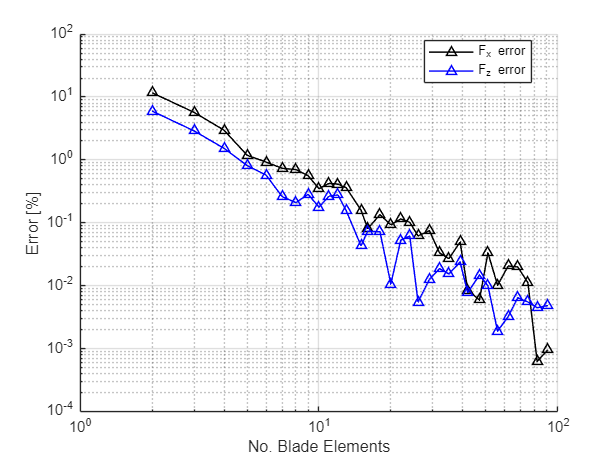

figure()
hold on
loglog(values, e_vec_x, "k-^", LineWidth=1, DisplayName="F_x error")
loglog(values, e_vec_z, "b-^", LineWidth=1, DisplayName="F_z error")
legend("Location","best")
set(gca, 'XScale', 'log', 'YScale', 'log')
grid on
xlabel("No. Blade Elements")
ylabel("Error [%]")

set(gcf, 'PaperPositionMode', 'auto')
print(gcf, './studies/rotor_mesh/variation_blade_elemetnts', '-depsc')  % EPS a cores

mass_payload = 20;
density = 1.225;
vehicle_position = [0; 0; 0];
vehicle_velocity = [50; 0; -20];
vehicle_orientation = [0; 0; 0];

Nb = 4;
Span = 1;
RootBladeDistance = 0.05;
root_theta = 10;
twist_rate = 0;
root_chord = 0.17;
lambda_chord = 1;
disk_area = pi * (Span - RootBladeDistance)^2;
induced_velocity = -1.5;

RPM = 500;

blade_integrator = 'Trapezoidal'; 

values = floor(logspace(0, 2, 50));
values = unique(values);
values(1)=[]

values =      2     3     4     5     6     7     8     9    10    11    12    13    15    16    18    20    22    24    26    29    32    35    39    42    47    51    56    62    68    75    82    91   100



azimutal_points_vec = values;
No_elements_vec = 100;

f_vec_x = zeros(length(azimutal_points_vec), length(No_elements_vec));
e_vec_x = zeros(length(azimutal_points_vec), length(No_elements_vec));

f_vec_y = zeros(length(azimutal_points_vec), length(No_elements_vec));
e_vec_y = zeros(length(azimutal_points_vec), length(No_elements_vec));

f_vec_z = zeros(length(azimutal_points_vec), length(No_elements_vec));
e_vec_z = zeros(length(azimutal_points_vec), length(No_elements_vec));

counter = 0;

for c = 1:length(azimutal_points_vec)
    for b = 1:length(No_elements_vec)

        azimutal_points = azimutal_points_vec(c);
        No_elements = No_elements_vec(b);

        counter = counter + 1;

        fprintf (">> [%d] E = %d | A = %d\n", counter, No_elements, azimutal_points)
        sim_init_rotor_simulation
        [F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
        f_vec_x(c, b) = F_rotor(1);
        f_vec_y(c, b) = F_rotor(2);
        f_vec_z(c, b) = F_rotor(3);

        clear SIM VEHICLE ROTOR BLADE ATMOSPHERE

    end
end

>> [1] E = 100 | A = 2
>> [2] E = 100 | A = 3
>> [3] E = 100 | A = 4
>> [4] E = 100 | A = 5
>> [5] E = 100 | A = 6
>> [6] E = 100 | A = 7
>> [7] E = 100 | A = 8
>> [8] E = 100 | A = 9
>> [9] E = 100 | A = 10
>> [10] E = 100 | A = 11
>> [11] E = 100 | A = 12
>> [12] E = 100 | A = 13
>> [13] E = 100 | A = 15
>> [14] E = 100 | A = 16
>> [15] E = 100 | A = 18
>> [16] E = 100 | A = 20
>> [17] E = 100 | A = 22
>> [18] E = 100 | A = 24
>> [19] E = 100 | A = 26
>> [20] E = 100 | A = 29
>> [21] E = 100 | A = 32
>> [22] E = 100 | A = 35
>> [23] E = 100 | A = 39
>> [24] E = 100 | A = 42
>> [25] E = 100 | A = 47
>> [26] E = 100 | A = 51
>> [27] E = 100 | A = 56
>> [28] E = 100 | A = 62
>> [29] E = 100 | A = 68
>> [30] E = 100 | A = 75
>> [31] E = 100 | A = 82
>> [32] E = 100 | A = 91
>> [33] E = 100 | A = 100


f_vec_x

f_vec_x =   178.3485
  123.7494
   89.1742
  103.6667
  105.6672
  105.4778
  105.8165
  106.4377
  106.6957
  106.5269


e_vec_x = (abs((f_vec_x - f_vec_x(end))/f_vec_x(end)) * 100)

e_vec_x =    67.6081
   16.2971
   16.1959
    2.5762
    0.6962
    0.8742
    0.5559
    0.0279
    0.2704
    0.1117


f_vec_y

f_vec_y = 1.0e-13 *

   -0.0501
   -0.2368
   -0.2842
         0
   -0.0947
   -0.4872
   -0.0711
   -0.0632
    0.1990
    0.0258


e_vec_y = (abs((f_vec_y - f_vec_y(end))/f_vec_y(end)) * 100)

e_vec_y = 1.0e+03 *

    0.4712
    1.8544
    2.2053
    0.1000
    0.8018
    3.7090
    0.6263
    0.5678
    1.3737
    0.0914


f_vec_z

f_vec_z = 1.0e+03 *

    1.6634
    1.1232
    1.2565
    1.2304
    1.2194
    1.2185
    1.2257
    1.2205
    1.2169
    1.2184


e_vec_z = (abs((f_vec_z - f_vec_z(end))/f_vec_z(end)) * 100)

e_vec_z =    36.4351
    7.8704
    3.0633
    0.9159
    0.0149
    0.0572
    0.5313
    0.1056
    0.1860
    0.0627


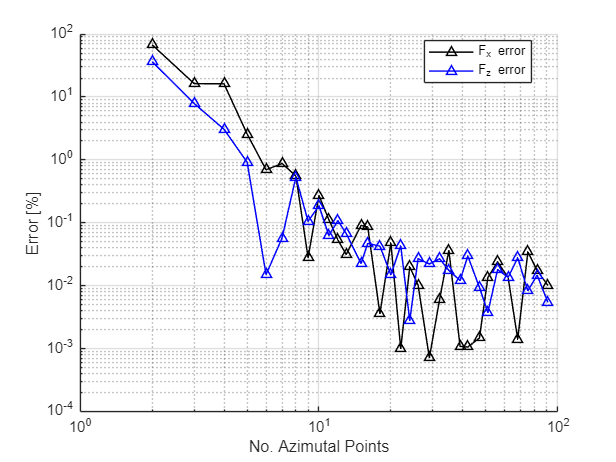

figure()
hold on
loglog(values, e_vec_x, "k-^", LineWidth=1, DisplayName="F_x error")
loglog(values, e_vec_z, "b-^", LineWidth=1, DisplayName="F_z error")
legend("Location","best")
set(gca, 'XScale', 'log', 'YScale', 'log')
grid on
xlabel("No. Azimutal Points")
ylabel("Error [%]")

set(gcf, 'PaperPositionMode', 'auto')
print(gcf, './studies/rotor_mesh/variation_azimutal_points', '-depsc')  % EPS a cores